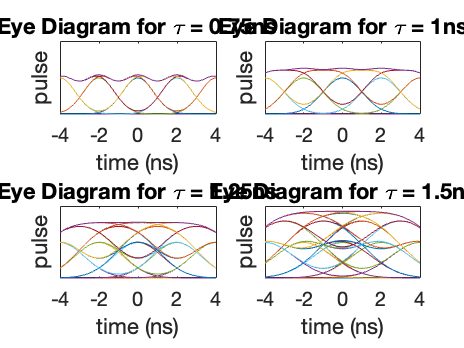

clear all
close all
D = 15; %15ps/nm/km
delta_lambda = 0.1; %nm

tau_0 = [0.8 1 1.25 1.5]; %ns
L = 0; %km

delta_tau = D*delta_lambda*L/1000; %ns
tau = (tau_0.^2 + delta_tau^2).^0.5; % pulse width considering dispersion
bitnumber = 5;
interval = 2; % ns
range = (bitnumber-1) * interval; %ns
resolution = 0.01;
P_0 =1;
t = -range/2:resolution:range/2;



for i=1:2^bitnumber
    i = i - 1;
    sequence = dec2binarr(i,bitnumber);
    P_025 = zeros(1,range/resolution+1);
    P_05 = zeros(1,range/resolution+1);
    P_1 = zeros(1,range/resolution+1);
    P_2 = zeros(1,range/resolution+1);
    P_logic05 = zeros(1,range/resolution+1)+1;


    for ii = 1:bitnumber
        if sequence(ii)==1    
            P_temp = P_0 * exp(-(t+range/2-ii*interval+interval).^2/2/tau(1)^2);
            P_025 = P_temp + P_025;
            P_temp = P_0 * exp(-(t+range/2-ii*interval+interval).^2/2/tau(2)^2);
            P_05 = P_temp + P_05;
            P_temp = P_0 * exp(-(t+range/2-ii*interval+interval).^2/2/tau(3)^2);
            P_1 = P_temp + P_1;
            P_temp = P_0 * exp(-(t+range/2-ii*interval+interval).^2/2/tau(4)^2);
            P_2 = P_temp + P_2;
        end
    end

    figure(1)
    subplot(221)
    plot(t,P_025)   
    hold on
    xlim([-(bitnumber-1) (bitnumber-1)])
    ylim([0 2])

    title('Eye Diagram for \tau = 0.75ns')
    xlabel('time (ns)') 
    ylabel('pulse') 
    set(gca,'YTick', [])

    subplot(222)
    plot(t,P_05)
    
    hold on
    xlim([-(bitnumber-1) (bitnumber-1)])
    ylim([0 2])

    title('Eye Diagram for \tau = 1ns')
    xlabel('time (ns)') 
    ylabel('pulse') 
    set(gca,'YTick', [])

    subplot(223)
    plot(t,P_1)
    hold on
    xlim([-(bitnumber-1) (bitnumber-1)])
    ylim([0 2])

    title('Eye Diagram for \tau = 1.25ns')
    xlabel('time (ns)') 
    ylabel('pulse') 
    set(gca,'YTick', [])

    subplot(224)
    plot(t,P_2)
    hold on
    xlim([-(bitnumber-1) (bitnumber-1)])
    ylim([0 2])

    title('Eye Diagram for \tau = 1.5ns')
    xlabel('time (ns)') 
    ylabel('pulse') 
    set(gca,'YTick', [])

end


exportgraphics(figure(1),'Assignment_2.png','Resolution',600)